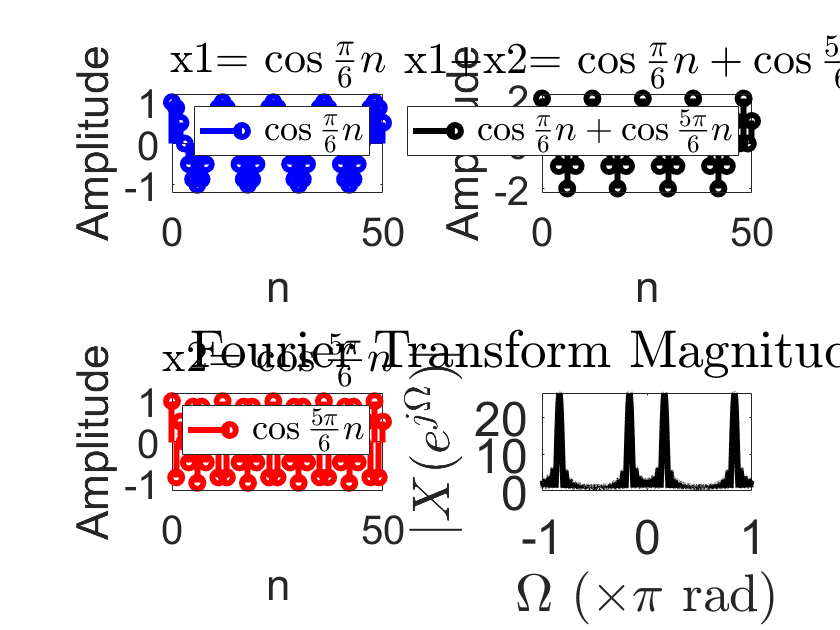

% Creating the x[n] as the sum of two sine signals
n = 0:50;
w1 = pi/6;
w2 = 5*pi/6;
x1 = cos(w1*n);
x2 = cos(w2*n);
x = x1 + x2;
w = -pi:0.001:pi;
X = dtft(n, x, w);

% Figure 1: Individual Cosine Signals
subplot(2,2,1)
stem(n, x1, 'blue', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{\pi}{6}n$'}, 'Interpreter', 'latex');
title('x1= $\cos \frac{\pi}{6}n$', 'Interpreter', 'latex');

subplot(2,2,3)
stem(n, x2, 'red', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -1.2 1.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{5\pi}{6}n$'}, 'Interpreter', 'latex');
title('x2= $\cos \frac{5\pi}{6}n$', 'Interpreter', 'latex');

% Figure 2: Sum of Cosine Signals
subplot(2,2,2)
stem(n, x, 'black', 'linewidth', 3);
set(gca, 'fontsize', 20);
axis([0 50 -2.2 2.2]);
xlabel('n');
ylabel('Amplitude');
legend({'$\cos \frac{\pi}{6}n+\cos \frac{5\pi}{6}n$'}, 'Interpreter', 'latex');
title('x1+x2= $\cos \frac{\pi}{6}n+\cos \frac{5\pi}{6}n$', 'Interpreter', 'latex');

% Figure 3: Fourier Transform Magnitude
subplot(2,2,4)
plot(w/pi, abs(X), 'black', 'linewidth', 3);
set(gca, 'fontsize', 24);
xlabel('$\Omega$ ($\times \pi$ rad)', 'Interpreter', 'latex');
ylabel('$|X(e^{j\Omega})|$', 'Interpreter', 'latex');
title('Fourier Transform Magnitude: $|X(e^{j\Omega})|$', 'Interpreter', 'latex');